# 2-QAM

## Generate Data for Transmission

rng(1) % Seed the random number generator
N=1000-100; % Length of the data
dat=sign(randn(N,1)+1i*sign(randn(N,1))); % Generate random data
txname='tx_x14_fake.dat'; % name of the tx data file

% start transmission with 100 -1s
negative = -1*ones(100,1)-1i*ones(100,1);
dat= [negative.' dat.'].'

dat =   -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i



% Upsample the data
pulse_width = 100;
x_us=upsample(dat,pulse_width);

% Convolve the signal with a pulse
pulse=ones(pulse_width,1);
x=conv(x_us,pulse);

% Write TX data to a file
write_usrp_data_file(x,txname)

## Read in Transmitted Data

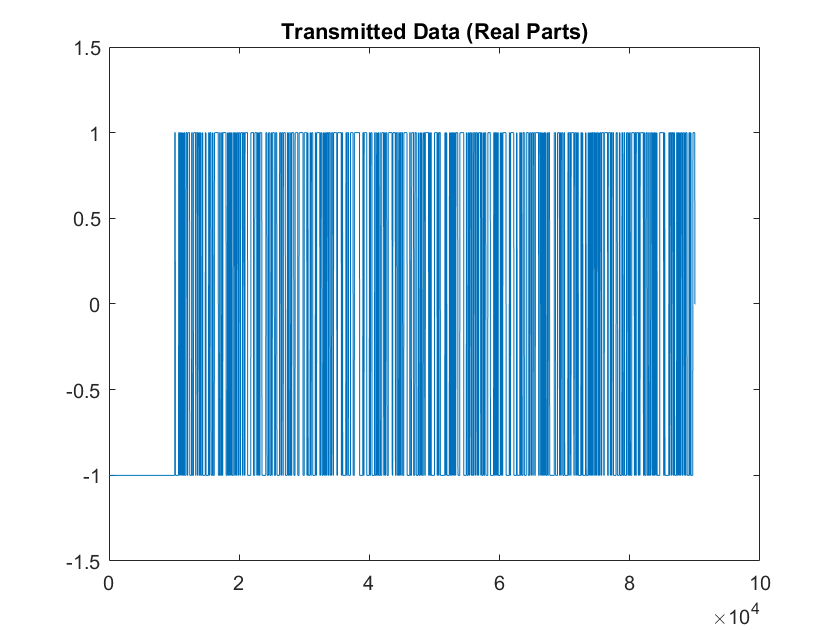

% Read in the Transmitted Data
txname='tx_x14.dat';
dat=read_usrp_data_file(txname);

% Plot the real part of the tx data
figure
plot(real(dat))
title('Transmitted Data (Real Parts)')
ylim([-1.5,1.5]);

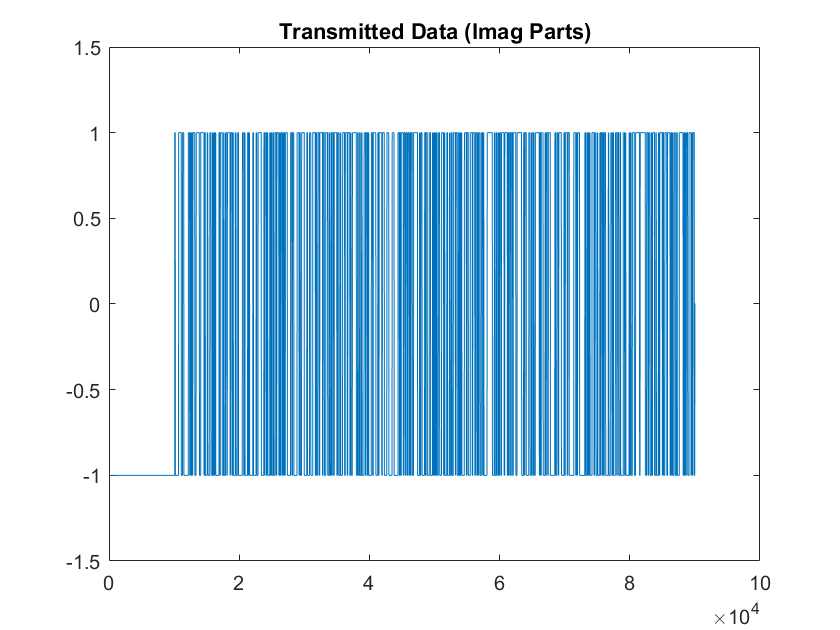


% Plot the imaginary part of the tx data
figure
plot(imag(dat))
title('Transmitted Data (Imag Parts)')
ylim([-1.5,1.5]);

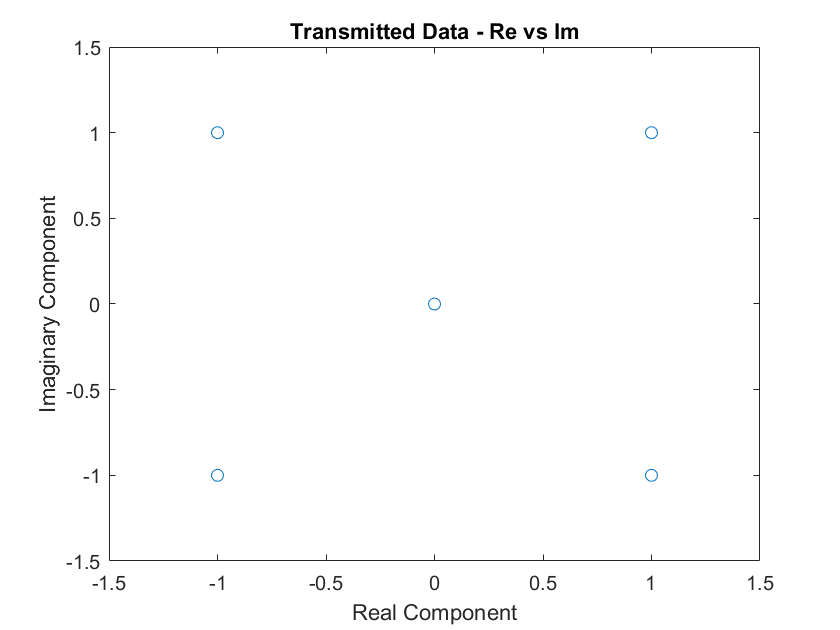


% Plot the real part vs the imaginary part of the tx
figure
plot(real(dat),imag(dat), 'o')
ylim([-1.5,1.5])
xlim([-1.5,1.5])
title('Transmitted Data - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Read in the Received Data

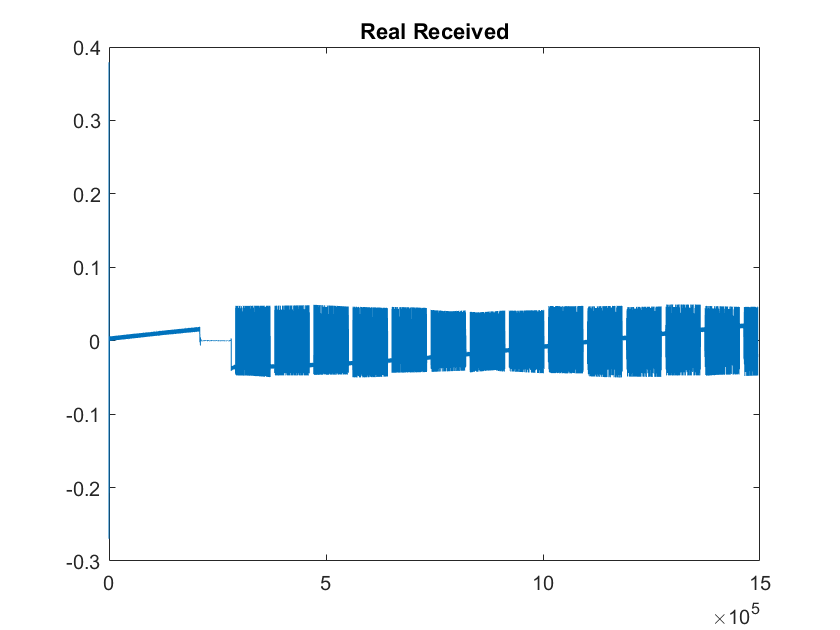

% Read in the received data
rxname='rx_x14.dat';
read=read_usrp_data_file(rxname);

% Plot the real part of rx
figure
plot(real(read))
%ylim([-1.5,1.5]);
title('Real Received')

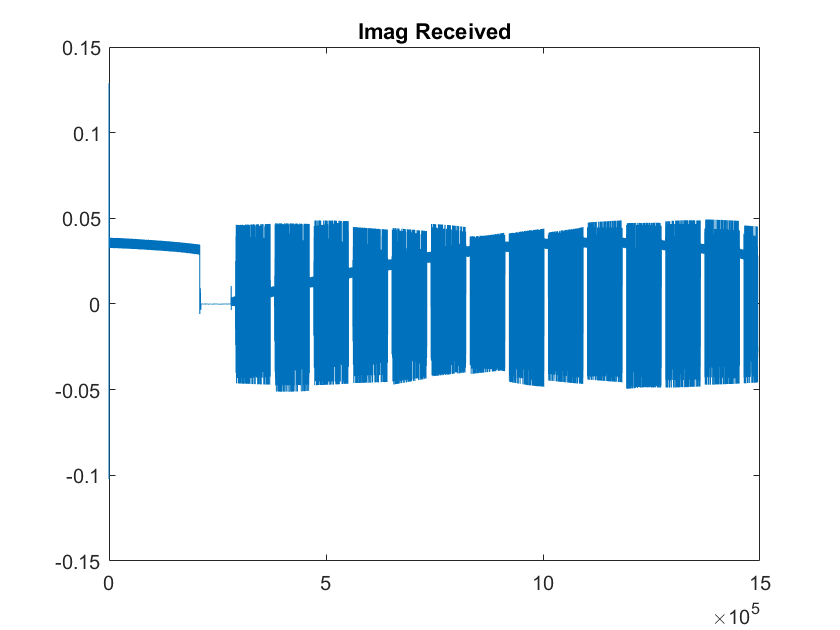


% Plot the imaginary part of rx
figure
plot(imag(read))
title('Imag Received')

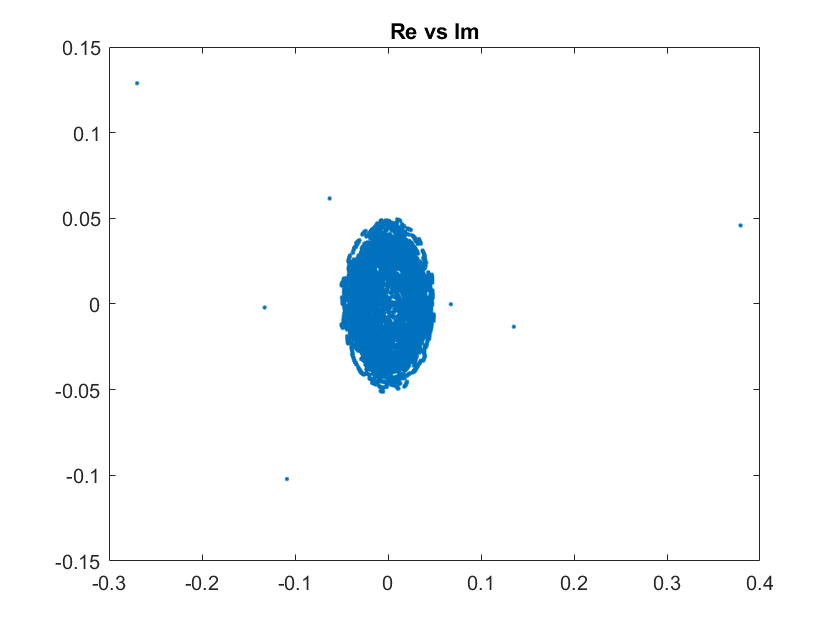


% Plot real vs imaginary components of the rx signal
figure
plot(real(read),imag(read),'.')
title('Re vs Im')

## Cross-correlation of RX and TX

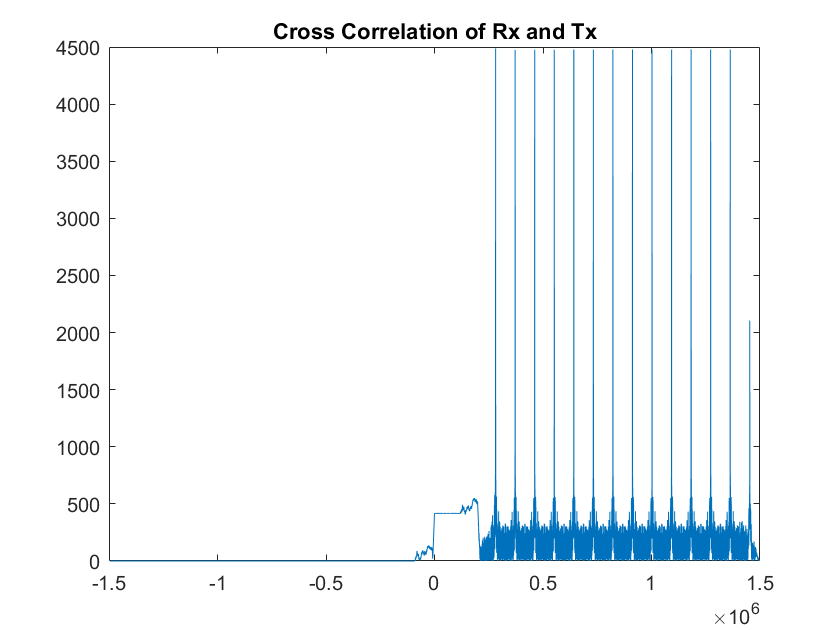

%Find cross-correlation of received and transmitted signals
[r, lags]=xcorr(read,dat);

% Plot Cross-correlation
plot(lags,abs(r))
title('Cross Correlation of Rx and Tx')

% xlim([-10^5 10^5])
% ylim([-.2 .2])

% Find the lag where the cross-correlation of rx/tx is greatest
% This indicates where the signal begins
startPos = lags(find(abs(r) == max(abs(r))))

startPos = 281591

## Adjust for phase shift

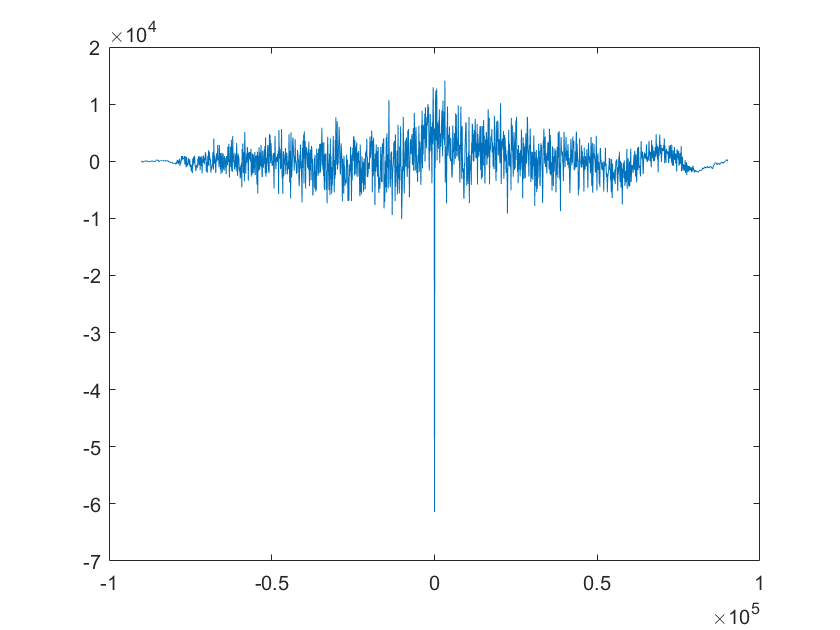

% Isolate the portion of the received signal corresponding to the data we
% sent
read_shifted=read(startPos:end);
signal_rx = read_shifted(1:length(dat));

% Cross-correlate real part of received signal and transmitted signal
% Tells us if our start position for the signal is correct
rx_mag_1 = sign(real(signal_rx)) + sign(imag(signal_rx));
[r, lags]=xcorr(real(rx_mag_1),real(dat));
plot(lags,r)


% If our signal always begins with -1s, we can fix the sign of our received
% data by multiplying by the negative of the sign of the first bit of the
% received data
signal_rx_sign = signal_rx; sign(signal_rx(1))*signal_rx;

% Solve for phi
% y[k]=x[k]e^j*(f_delta*k+phi)+n[k]
% x[k]=e^j(pi/4 + m*pi/2)
% y[k]^4 = e^(j*pi) * e^(4*f_delta*k+4*theta)
y_norm=signal_rx_sign./rms(abs(signal_rx_sign));
y_norm_4=y_norm.^4;

% Find the maximum values of the real and imaginary components of the fft
% of y[k]^4
fft_y = fft(y_norm_4);
real_max = max(real(fft_y));
im_max = max(imag(fft_y));

% 4*phi + pi = atan(im_max / real_max)
phi = (atan(im_max/real_max) - pi)/4

phi = -0.7717

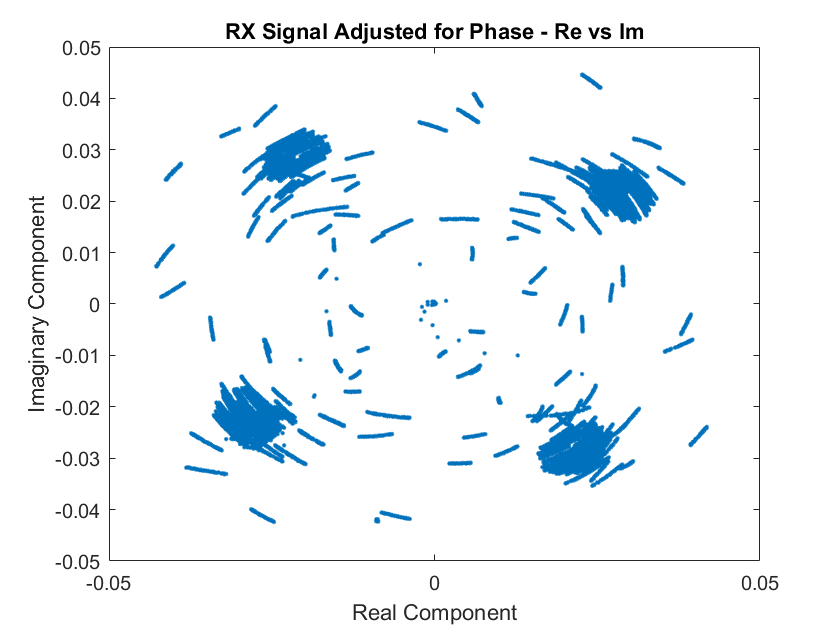


% Find complex exponential to adjust for phase offset
f_delta = 0; % adjusts for clocks being unsynchronized
Fs = 500000; % sampling frequency
k=1:length(signal_rx_sign);
offset=exp(-j*(f_delta*(k-1)*1/Fs+phi));

% Multiply rx signal by the complex exponential to adjust for phase offset
read_offset=times(signal_rx_sign,offset.');

% Plot real vs imaginary of adjusted rx signal
figure
plot(real(read_offset),imag(read_offset),'.')
title('RX Signal Adjusted for Phase - Re vs Im')
xlabel('Real Component')
ylabel('Imaginary Component')

## Error Calculation

% Downsample TX signal to get original signal
data_ds = downsample(dat,pulse_width);

% Downsample RX signal
rx_ds = downsample(read_offset,pulse_width,pulse_width/2);

% Find number of errors in real and imaginary components, downsampling the
% rx signal
error_real=sign(real(rx_ds))-sign(real(data_ds));
error_imag=sign(imag(rx_ds))-sign(imag(data_ds));
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));

% Sum errors and calculate error rate
err_total = err_real + err_imag;
err_rate=err_total/(length(rx_ds)*2);
err_rate

err_rate = 0.0011

## Overlay TX and RX Signals

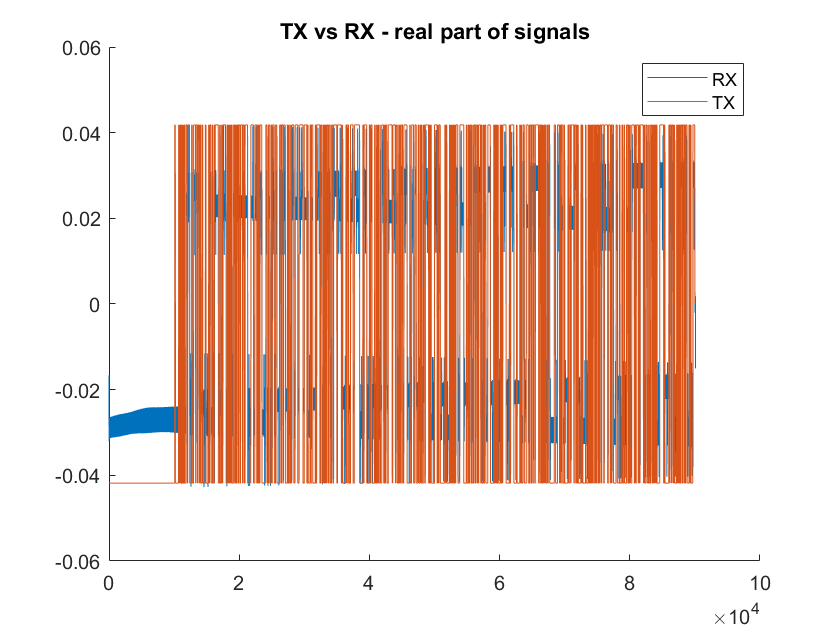

figure
hold on;
plot(real(read_offset))
plot(real(dat)*max(real(read_offset)))
legend("RX", "TX");
ylim([-.06,.06])
title("TX vs RX - real part of signals")
hold off;

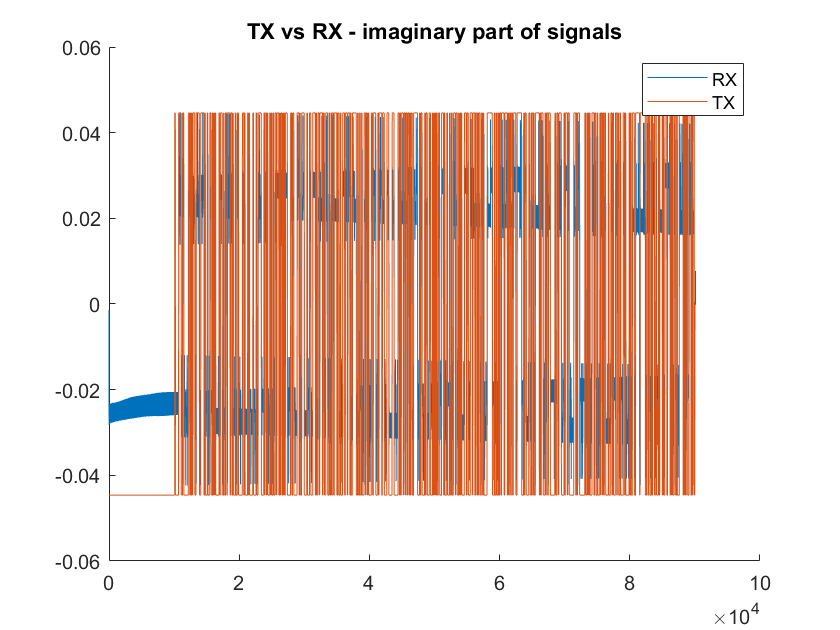


figure
hold on;
plot(imag(read_offset))
plot(imag(dat)*max(imag(read_offset)))
legend("RX", "TX");
ylim([-.06,.06])
title("TX vs RX - imaginary part of signals")
hold off;